# Scale an Image to Fit a Page

If an image does not fit on a page in a report, use an `mlreportgen.dom.Image` object to scale the image so that it fits.

Save an image of a plot.

x = 0:pi/100:2*pi;
y = sin(x);
plot(x,y);

saveas(gcf,'myPlot_img.png');

Include the image in a report without specifying the width or height.

import mlreportgen.dom.*
d = Document('myImageReport2','docx');

img = Image('myPlot_img.png');
append(d,img);

close(d);
rptview(d);

The image does not fit on the page.

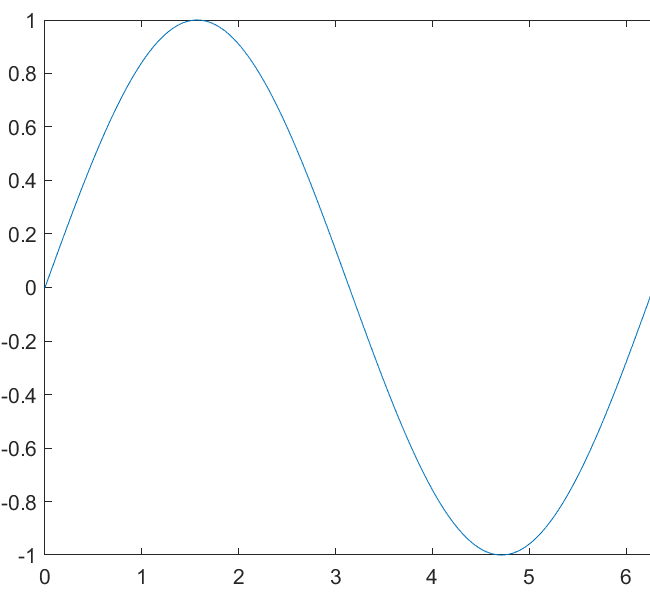

Include the same image in another report. To make sure that it fits on the page, add an `mlreportgen.dom.ScaleToFit` object to the `Style` property of the `mlreportgen.dom.Image` object.

d = Document('myImageReport3','docx');

plot1 = Image('myPlot_img.png');
plot1.Style = [plot1.Style {ScaleToFit(true)}];
append(d,plot1);

close(d);
rptview(d);

The image fits on the page.

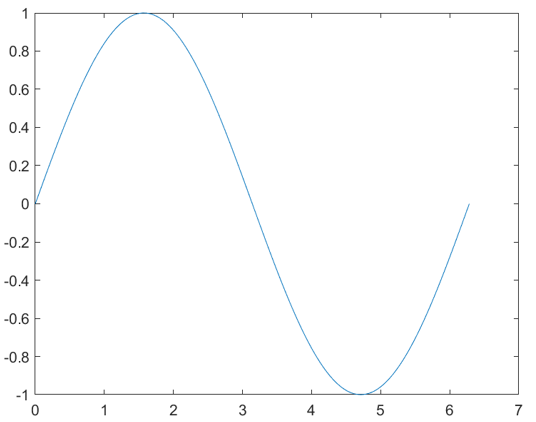

*Copyright 2020 The MathWorks, Inc.*